# Identificazione in greybox

Motivazione:

- L'identificazione in anello aperto non consente di limitare l'andamento del sistema, causando possibili urti o il raggiungimento dei limiti del sistema

Obiettivi:

- analizzare le differenza fra la stima in anello aperto e anello chiuso al variare delle frequenza

- analizzare l'effetto del transitorio

## Sistema simulato

uso un sistena motore-trasmissione elastica-carico

clear all;close all;clc;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi

dt=1e-3;

load joint3_ident
load joint3_validation.mat

il sistema ha 

- due uscite: posizione motore e posizione link; 

- un ingresso: la coppia. 

Sono state effettuate due prove di sweep in frequenza (stesso controllore:

- identificazione da 0.1 a 500 rad/s, in anello chiuso con feedforward di coppia 50Nm di ampliezza. Durata 360 s

- validazione da 1 a 50 rad/s, in anello chiuso con feedforward di coppia 60Nm di ampliezza. Durata 120 s

In questo esempio ci interessa stimare il legame coppia velocità. 

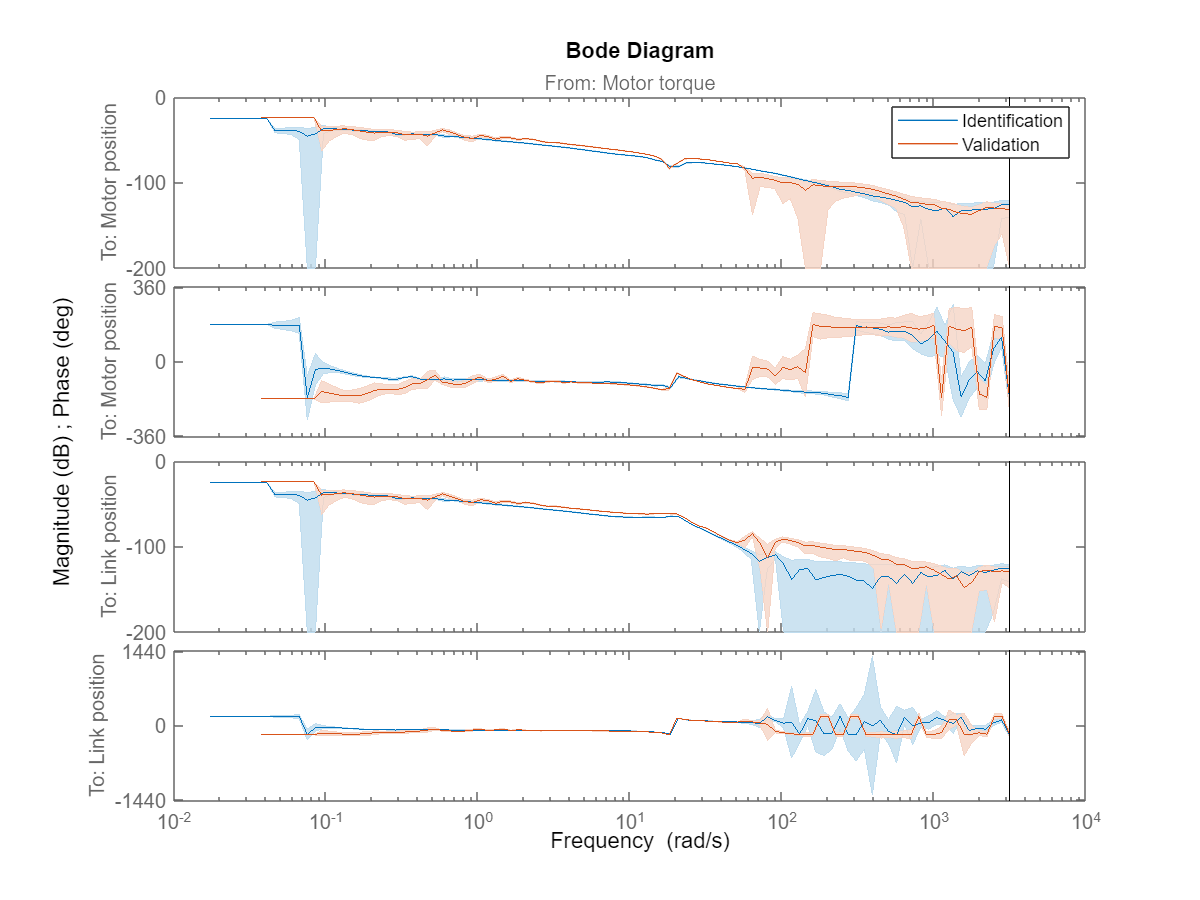

figure(1)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

h=bodeplot(joint3_freq_resp_ident, bode_opts);
hold on
grid on
showConfidence(h,3)
h=bodeplot(joint3_freq_resp_validation, bode_opts);
legend('Identification','Validation')

## Identificazione in grey-box

Dalla risposta e dalla conoscenza del sistema ipotizzo un sistema motore-trasmissione elastica carico:


$$J_m \ddot{q}_m=\tau_m - c_m \dot{q}_m - k(q_m -q_l)-c(\dot{q}_m-\dot{q}_l)$$



$$J_l \ddot{q}_m= k(q_m -q_l)+
c(\dot{q}_m-\dot{q}_l)$$


dove trascuro attrivo statico.

Il modello è implementato nella funzione sea_model. Ipotizzo dei valori di partenza (da datasheet, per tentativi)

Jm=0.1; % motor inertia 
Jl=2; % link inertia
k=2000; % spring stiffness
c=10;  % spring damping
cm=0.2; % motor viscuous friction

parameters={
    'Jm',Jm;
    'Jl',Jl;
    'k',k;
    'c',c;
    'cm',cm
    };
sea_model = idgrey(@sea_model,parameters,'c');

Impongo considero solo il range di frequenze centrale

peso=ones(length(joint3_freq_resp_ident.Frequency),1);
wpeso0=5;
wpeso1=300;
peso(joint3_freq_resp_ident.Frequency<wpeso0)=1e-5;
peso(joint3_freq_resp_ident.Frequency>wpeso1)=1e-5;
grey_opt = greyestOptions('WeightingFilter',peso);

Stimo il modello

modello_greybox=greyest(joint3_freq_resp_ident,sea_model,grey_opt);

Comparo con un modello black box del quarto ordine

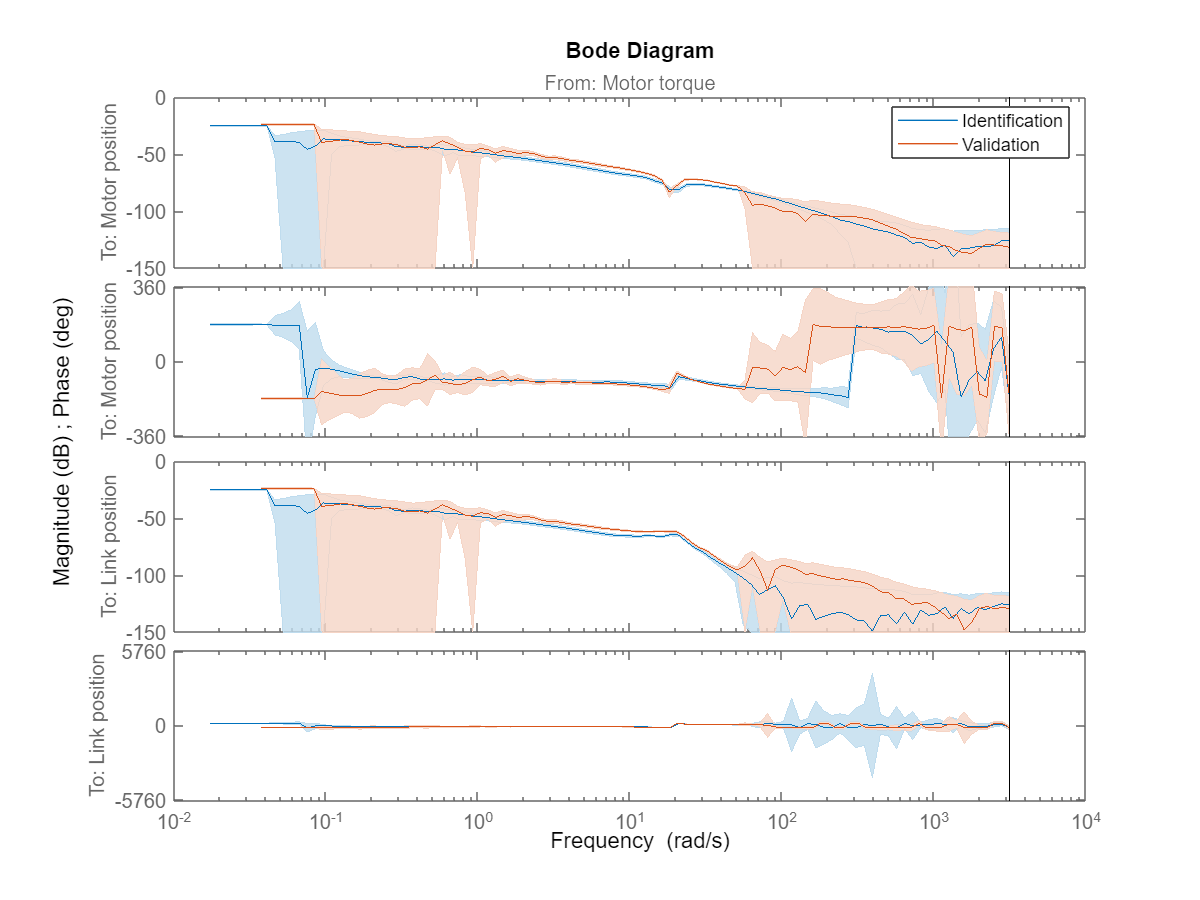

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo = ssest(joint3_freq_resp_ident,4,opts);

figure(2)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

bodeplot(joint3_freq_resp_ident, bode_opts);
hold on
grid on
showConfidence(h,3)

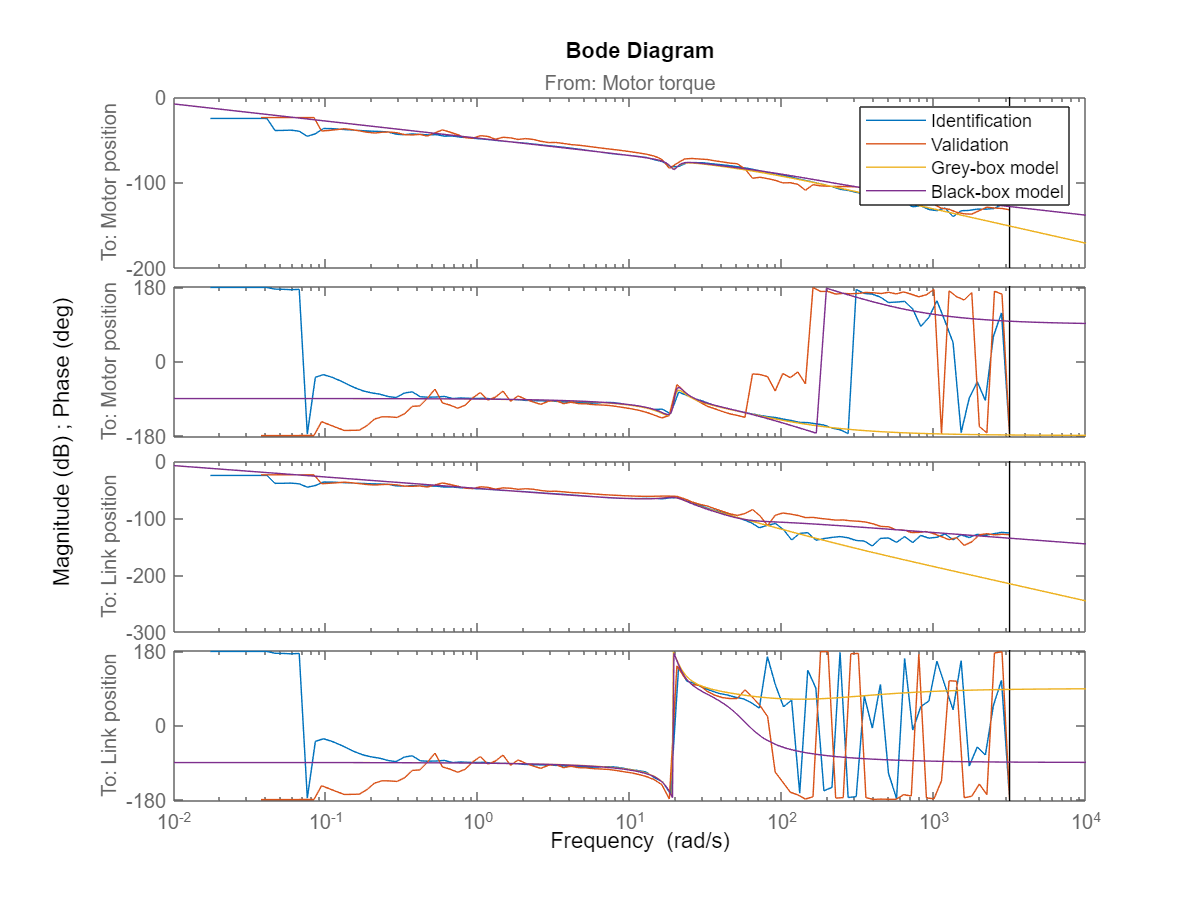

bodeplot(joint3_freq_resp_validation, bode_opts);
bodeplot(modello_greybox, bode_opts);
bodeplot(modello_continuo, bode_opts);
legend('Identification','Validation','Grey-box model','Black-box model')

hold off